# GradCam Analysis

addpath 'E:\Padova\Thesis\themoonrocks';
addpath 'E:\Padova\Thesis\themoonrocks\Images';

% Creating directory to save the visualizations
learning = '10C-DL';
patch = 'mi_map_03_n17e309n16e310sc-11-4';
Dir1 = (['GradCam/' patch]);
Dir2 = learning;
if ~exist(Dir1, 'dir')
    mkdir(['./' Dir1 '/' Dir2])
end

prompt = "Please enter the path to image data you want to visualise."

prompt = "Please enter the path to image data you want to visualise."

% file1 = "E:\Padova\Thesis\themoonrocks\Images\mi_map_03_n17e309n16e310sc.img";
file1 = input(prompt, "s");

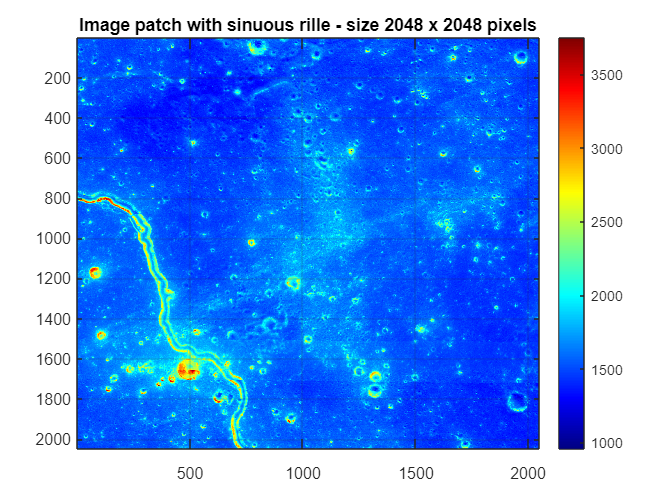

global patchSize
global currentCombination
global chnr

patchSize = 2048;
currentCombination = [1,2,10];
chnr = 3;

Image = readPatch(file1);
img = Image(:,:,2);
Fig = imagesc(img);
title('Image patch with sinuous rille - size 2048 x 2048 pixels');
colormap jet
colorbar
grid on

% Saving the Original Image we are testing the patches from
prompt = "Please enter the path to image data you want to visualise.";
filename = input(prompt, "s");
%filename = "E:\Padova\Thesis\themoonrocks\Images\mi_map_03_n17e309n16e310sc-11-4.img";
global currentCombination
global chnr
global patchSize
patchSize = 100;
currentCombination = [1,2,10];
chnr = 3;
Image = readPatch(filename);

img = Image(:,:,2);
Fig = imagesc(img);
title('Image patch with sinuous rille - size 100 x 100 pixels');
colormap jet
colorbar
grid on

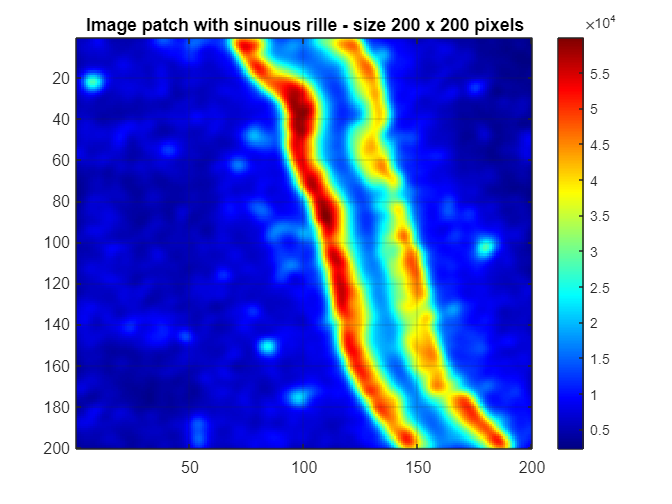

% Saving the Original Image we are testing the patches from
prompt = "Please enter the path to image data you want to visualise.";
filename = input(prompt, "s");
%filename = "E:\Padova\Thesis\themoonrocks\Images\200\mi_map_03_n17e309n16e310sc-6-2.img";

global patchSize
global currentCombination
global chnr

Image = readPatchWithProcessing(filename);
img = Image(:,:,2);
Fig = imagesc(img);
title('Image patch with sinuous rille - size 200 x 200 pixels');
colormap jet
colorbar
grid on

% Figure contains an axes object. The axes object contains an object of type image.
% Classify the image to get the class label.
label = classify(mynetOSAug,Image)

label = categorical
     sinuous-rille-100-100 


% Use gradCAM to determine which parts of the image are important to the classification result.
scoreMap = gradCAM(mynetOSAug,Image, label);

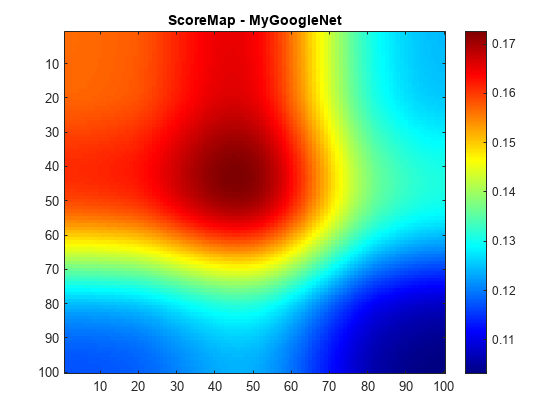

% h1 = figure;
% imagesc(Image(:,:,1))
% title('Altitude')
% colormap jet
% colorbar
% saveas(h1,['./' Dir1 '/' Dir2 '/' 'Altitude Channel' networkName num2str(patchSize) '.png'])
% close(h1)
% 
% h2 = figure;
% imagesc(Image(:,:,2))
% title('Wavelength')
% colormap jet
% colorbar
% saveas(h2,['./' Dir1 '/' Dir2 '/' 'Visible Spectrum' networkName num2str(patchSize) '.png'])
% close(h2)

h3 = figure;
imagesc(scoreMap)
title(['ScoreMap - ' networkName])
colormap jet
colorbar
saveas(h3,['./' Dir1 '/' Dir2 '/' 'Focus Region' networkName num2str(patchSize) '.png'])